# SINR Map for a 5G Urban Macro-Cell Test Environment

This example shows how to construct a 5G urban macro-cell test environment and visualize the signal-to-interference-plus-noise ratio (SINR) on a map. The test environment is based on the guidelines defined in Report ITU-R M.[IMT-2020.EVAL] [1] for evaluating 5G radio technologies. This report defines several test environments and usage scenarios in Section 8.2. The test environment in this example is based on the urban environment with high user density and traffic loads focusing on pedestrian and vehicular users (Dense Urban-eMBB). The test environment includes a hexagonal cell network as well as a custom antenna array that is implemented using Phased Array System Toolbox™.

## Define Network Layout

The test environment guidelines for 5G technologies reuse the test network layout for 4G technologies defined in Section 8.3 of Report ITU-R M.2135-1 [2], which is shown below. The layout consists of 19 sites placed in a hexagonal layout, each with 3 cells. The distance between adjacent sites is the inter-site distance (ISD) and depends on the test usage scenario. For the Dense Urban-eMBB test environment, the ISD is 200 m. 

Create the locations corresponding to cell sites in the network layout, using MathWorks Glasgow as the center location.

load('../../data/CRB/PEARL_HARBOR.mat', 'Pearlharbor')

% Initialize arrays for distance and angle from center location to each cell site, where
% each site has 3 cells
numCellSites = size(Pearlharbor,1);


## Define Cell Parameters

Each cell site has three transmitters corresponding to each cell. Create arrays to define the names, latitudes, longitudes, and antenna angles of each cell transmitter. 

% Initialize arrays for cell transmitter parameters
cellLats = [];
cellLons = [];
for i = 1:numCellSites
   cellLats = [cellLats Pearlharbor(i).trilat];
   cellLons = [cellLons Pearlharbor(i).trilong];
end

isd = 200;


## Create Transmitter Sites

Create transmitter sites using parameters defined above as well as configuration parameters defined for Dense Urban-eMBB. Open the basemap picker in [Site Viewer](docid:antenna_ug.mw_5ec4b472-6207-4844-91ab-810b8435133d) by clicking the second button from the right. Select "OpenStreetMap" to choose a basemap with streets and labels.

% Define transmitter parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL]
fq = 2.4e9; % Carrier frequency (2.4 GHz) for Dense Urban-eMBB
antHeight = 1; % m
txPowerDBm = -25; % Total transmit power in dBm
txPower = 10.^((txPowerDBm-30)/10); % Convert dBm to W

% Create cell transmitter sites
txs = txsite('Latitude',cellLats, ...
    'Longitude',cellLons, ....
    'AntennaHeight',antHeight, ...
    'TransmitterFrequency',fq, ...
    'TransmitterPower',txPower);

% Show sites on a map
show(txs);

## Create Antenna Element

Section 8.5 of ITU-R report [1] defines antenna characteristics for base station antennas. The antenna is modeled as having one or more antenna panels, where each panel has one or more antenna elements. Use Phased Array System Toolbox to implement the antenna element pattern defined in the report.

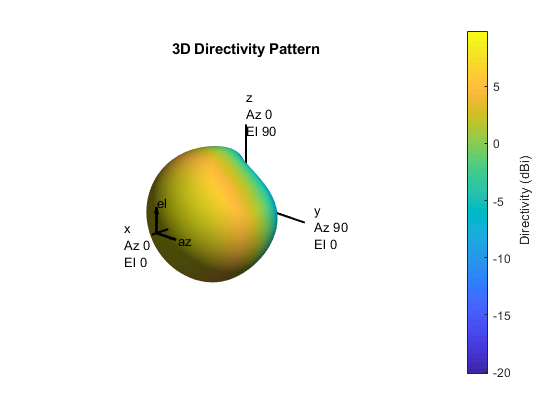

% Define pattern parameters
azvec = -180:180;
elvec = -90:90;
Am = 30; % Maximum attenuation (dB)
tilt = 0; % Tilt angle
az3dB = 65; % 3 dB bandwidth in azimuth
el3dB = 65; % 3 dB bandwidth in elevation

% Define antenna pattern
[az,el] = meshgrid(azvec,elvec);
azMagPattern = -12*(az/az3dB).^2;
elMagPattern = -12*((el-tilt)/el3dB).^2;
combinedMagPattern = azMagPattern + elMagPattern;
combinedMagPattern(combinedMagPattern<-Am) = -Am; % Saturate at max attenuation
phasepattern = zeros(size(combinedMagPattern));

% Create antenna element
antennaElement = phased.CustomAntennaElement(...
    'AzimuthAngles',azvec, ...
    'ElevationAngles',elvec, ...
    'MagnitudePattern',combinedMagPattern, ...
    'PhasePattern',phasepattern);
   
% Display radiation pattern
f = figure;
pattern(antennaElement,fq);

## Display SINR Map for Single Antenna Element

Visualize SINR for the test scenario using a single antenna element and the free space propagation model. For each colored location on the map, the signal source is the cell with the greatest signal strength, and all other cells are sources of interference.

% Assign the antenna element for each cell transmitter
for tx = txs
    tx.Antenna = antennaElement;
end

% Define receiver parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL] 
bw = 20e6; % 20 MHz bandwidth
rxNoiseFigure = 7; % dB
rxNoisePower = -174 + 10*log10(bw) + rxNoiseFigure;
rxGain = 0; % dBi
rxAntennaHeight = 1.5; % m

% Display SINR map
if isvalid(f)
    close(f)
end
txs

txs =   1×1109 txsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    TransmitterFrequency
    TransmitterPower


sinr(txs,'close-in', ...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',rxAntennaHeight, ...
    'ReceiverNoisePower',rxNoisePower, ...    
    'MaxRange',isd, ...
    'Resolution',isd/20, ...
    'ColorLimits', [-5,0])

Error using nan
Requested 3044916x1109 (25.2GB) array exceeds maximum array size preference. Creation of arrays greater than this limit may take a long time and cause MATLAB to become unresponsive. See array size limit or preference panel for more information.

Error in rfprop.internal.MapUtils.georange (line 149)
            gc = nan(numel(lats),numel(sites));

Error in 

## Summary

This example shows how to construct a 5G urban macro-cell test environment consisting of a hexagonal network of 19 cell sites, each containing 3 sectored cells. The signal-to-interference-plus-noise ratio (SINR) is visualized on a map for different antennas. The following observations are made:

- A rectangular antenna array can provide greater directionality and therefore peak SINR values than use of a single antenna element.

- The outward-facing lobes on the perimeter of the SINR map represent areas where less interference occurs. A more realistic modelling technique would be to replicate, or wrap around, cell sites to expand the geometry so that perimeter areas experience similar interference as interior areas.

- Using a rectangular antenna array, a propagation model that estimates increased path loss also results in higher SINR values due to less interference.

- Two antenna elements are tried in the antenna array: an equation-based element using Phased Array System Toolbox and a patch antenna element using Antenna Toolbox. These produce similar SINR maps.

## References

[1] Report ITU-R M.[IMT-2020.EVAL], "Guidelines for evaluation of radio interface technologies for IMT-2020", 2017. https://www.itu.int/md/R15-SG05-C-0057

[2] Report ITU-R M.2135-1, "Guidelines for evaluation of radio interface technologies for IMT-Advanced", 2009. https://www.itu.int/dms_pub/itu-r/opb/rep/R-REP-M.2135-1-2009-PDF-E.pdf

[3] Sun, S.,Rapport, T.S., Thomas, T., Ghosh, A., Nguyen, H., Kovacs, I., Rodriguez, I., Koymen, O.,and Prartyka, A. "Investigation of prediction accuracy, sensitivity, and parameter stability of large-scale propagation path loss models for 5G wireless communications." *IEEE Transactions on Vehicular Technology*, Vol 65, No.5, pp.2843-2860, May 2016.

*Copyright 2012 The MathWorks, Inc.*